% Electrocoagulation tank
clear all

rho_w = 998; % Water density (kg/m^3)
r = 1; % Tank radius (m)
h = 2; % Tank height (m)
V_wat = 5; % Water volume (m^3)
h_wat = V_wat / (pi * r^2); % Water height (m)

Vdoth = 2.39; % Hot water flow rate (m^3/h)
Vdotg = 0.9; % Gas flow rate (m^3/h)
Vdotc = 1.5; % Cold water flow rate (m^3/h)
Vdot = Vdoth+Vdotc+Vdotg;

mdot1 = 2.5 * rho_w / 3600; % kg/s (assuming water density ~ 1000 kg/m^3)
mdot2 = 1.5 * rho_w / 3600; % kg/s
mdot3 = 1.0 * rho_w / 3600; % kg/s

SA_a = pi * r^2; % Surface area of the top (m^2)
SA_t = 2 * pi * r * h_wat; % Lateral surface area (m^2)

cp = 4200; % Specific heat capacity (J/kg°C)
Tref = 283.15; % Reference temperature (K)
T60 = 273.15 + 60; % Hot water temperature (K)
T15 = 273.15 + 15.48; % Cold water temperature (K)

U_ss = 16; % Side surface heat transfer coefficient (W/m^2°C)
U_a = 25; % Top surface heat transfer coefficient (W/m^2°C)

Tinit = (mdot1 * T60 + mdot2 * T15 + mdot3 * Tref) / (mdot1 + mdot2 + mdot3);
fprintf('Tinit: %.2f°C\n', Tinit-273.15);

Tinit: 36.64°C


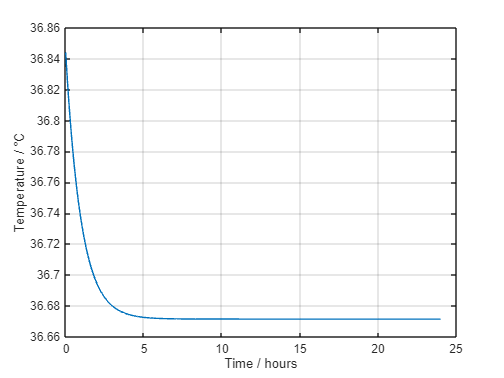


dt = 60; % Time step (s)
T(1) = Tinit+0.2; % Initial temperature (K)
t(1) = 0;

for i = 2:((3600*24)/dt)+1
    t(i) = (i-1)*dt;
    Q_hin = mdot1 * cp * (T60 - Tref);
    Q_cin = mdot2 * cp * (T15 - Tref);
    Q_gin = mdot3 * cp * (Tref - Tref);
    Q_a = U_a * SA_a * (T(i-1) - Tref);
    Q_t = U_ss * SA_t * (T(i-1) - Tref);
    Q_out = Vdot/3600 * rho_w * cp * (T(i-1) - Tref);
    
    dTdt = (Q_hin + Q_cin - Q_a - Q_t - Q_out) / (V_wat * rho_w * cp);
    T(i) = T(i-1) + dt * dTdt;
end

figure;
plot(t/(3600), T-273.15);
xlabel('Time / hours');
ylabel('Temperature / °C');
grid on;

fprintf('Steady state temperature of water in T-A03: %.2f°C\n', T(end) - 273.15);

Steady state temperature of water in T-A03: 36.67°C


%S-A02

A_req = 104210/24000 %Area required for surface overflow rate of 24000L/d/m2

A_req = 4.3421

d = sqrt(A_req*4/pi)

d = 2.3513

t_res = 2; %hr
V = (t_res*104.210/24) + 2.5 ; %vol of tank plus extra space so don't overflow
h_cyl = V/A_req %height of the cyclindrical part of the tank

h_cyl = 2.5758


h_cone = (d/2) * (sin(0.0785)/sin(1.492)) %depth of cone with 4.5deg angle down

h_cone = 0.0925

V_cone = pi*(d/2)^3*h_cone/3;
hyp_cone = sqrt(h_cone^2 + (d/2)^2); %length of slant
Vtot = V+V_cone;

hspace = (Vtot - 104.21/12)/(d^2 * pi/4) %height diff between nominal water level and tank top

hspace = 0.6120

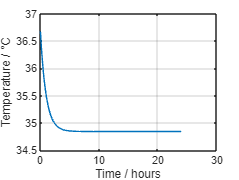



SA_st = pi*d*(h_cyl-hspace) + hyp_cone*pi*d/2; %Surface area of tank 
SA_sa = A_req;%surface area in contact with air
T2(1) = T(end);
t2(1) = 0;

for i = 2:((3600*24)/dt)+1
    t2(i) = (i-1)*dt;
    Q2_in = Vdot/3600 * rho_w * cp * (T(end) - Tref);
    Q2_a = U_a * SA_sa * (T2(i-1) - Tref);
    Q2_t = U_ss * SA_st * (T2(i-1) - Tref);
    Q2_out = Vdot/3600 * rho_w * cp * (T2(i-1) - Tref);
    
    dT2dt = (Q2_in - Q2_a - Q2_t - Q2_out) / (V_wat * rho_w * cp);
    T2(i) = T2(i-1) + dt * dT2dt;
end

figure;
plot(t2/(3600), T2-273.15);
xlabel('Time / hours');
ylabel('Temperature / °C');
grid on;

fprintf('Steady state temperature of water in S-A01: %.2f°C\n', T2(end) - 273.15);

Steady state temperature of water in S-A01: 34.84°C
